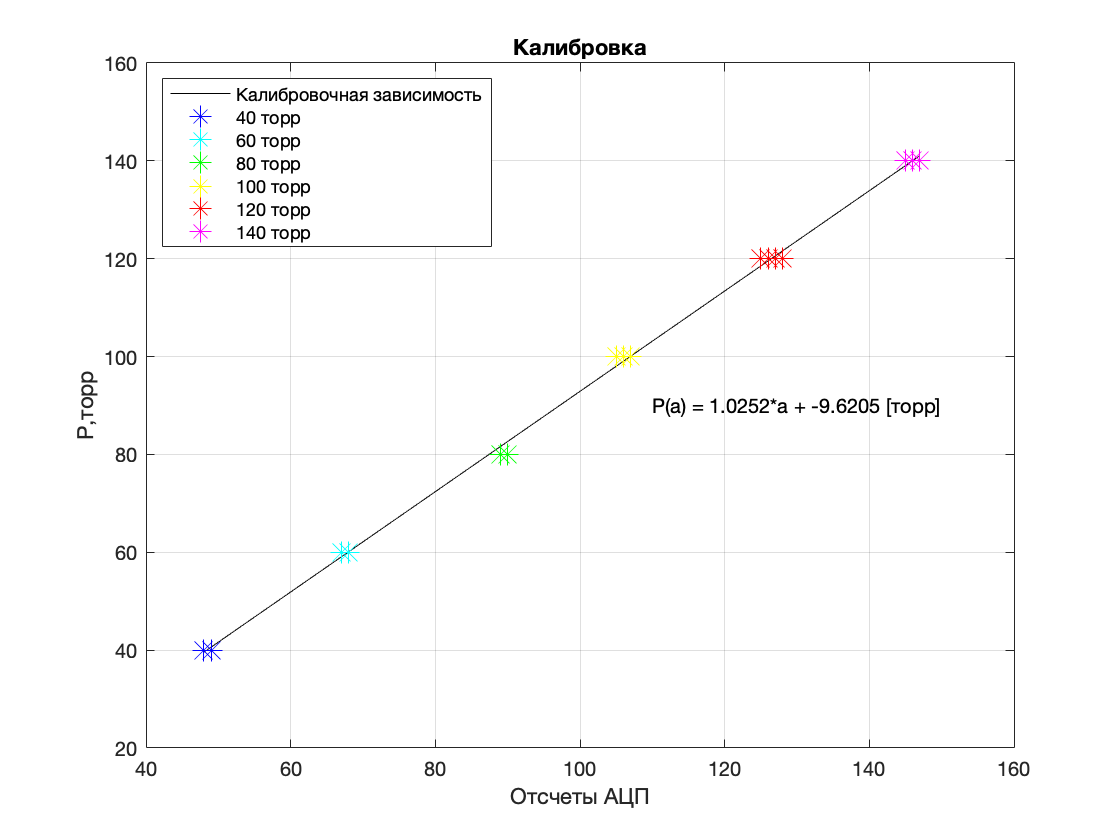

a40 = load('/Users/karimvafin/Downloads/data/calibration_1.txt')';
a60 = load('/Users/karimvafin/Downloads/data/calibration_2.txt')';
a80 = load('/Users/karimvafin/Downloads/data/calibration_3.txt')';
a100 = load('/Users/karimvafin/Downloads/data/calibration_4.txt')';
a120 = load('/Users/karimvafin/Downloads/data/calibration_5.txt')';
a140 = load('/Users/karimvafin/Downloads/data/calibration_6.txt')';

torr40 = ones(1, length(a40)).*40;
torr60 = ones(1, length(a60)).*60;
torr80 = ones(1, length(a80)).*80;
torr100 = ones(1, length(a100)).*100;
torr120 = ones(1, length(a120)).*120;
torr140 = ones(1, length(a140)).*140;

a = [a40 a60 a80 a100 a120 a140];
torr = [torr40 torr60 torr80 torr100 torr120 torr140];

N = 1;
k = polyfit(a, torr, N);
torr1 = 0;


for q = 0:N
    torr1 = torr1 + k(N-q+1) * a.^q;
end

f1 = figure('Name', 'Калибровка', 'NumberTitle','off');
figure(f1);
plot(a, torr1, 'Color','k');
grid on;
title('Калибровка');
ylabel('P,торр');
xlabel('Отсчеты АЦП');
hold on
plot(a40, torr40, 'b*','MarkerSize',10);
plot(a60, torr60, 'c*','MarkerSize',10);
plot(a80, torr80, 'g*','MarkerSize',10);
plot(a100, torr100, 'y*','MarkerSize',10);
plot(a120, torr120, 'r*','MarkerSize',10);
plot(a140, torr140, 'm*','MarkerSize',10);
legend('Калибровочная зависимость', '40 торр','60 торр','80 торр','100 торр','120 торр','140 торр','Location','northwest');
text(110,90, ['P(a) = ',num2str(k(1)),'*a + ', num2str(k(2)), ' [торр]']);
saveas(f1, "calibration.png");

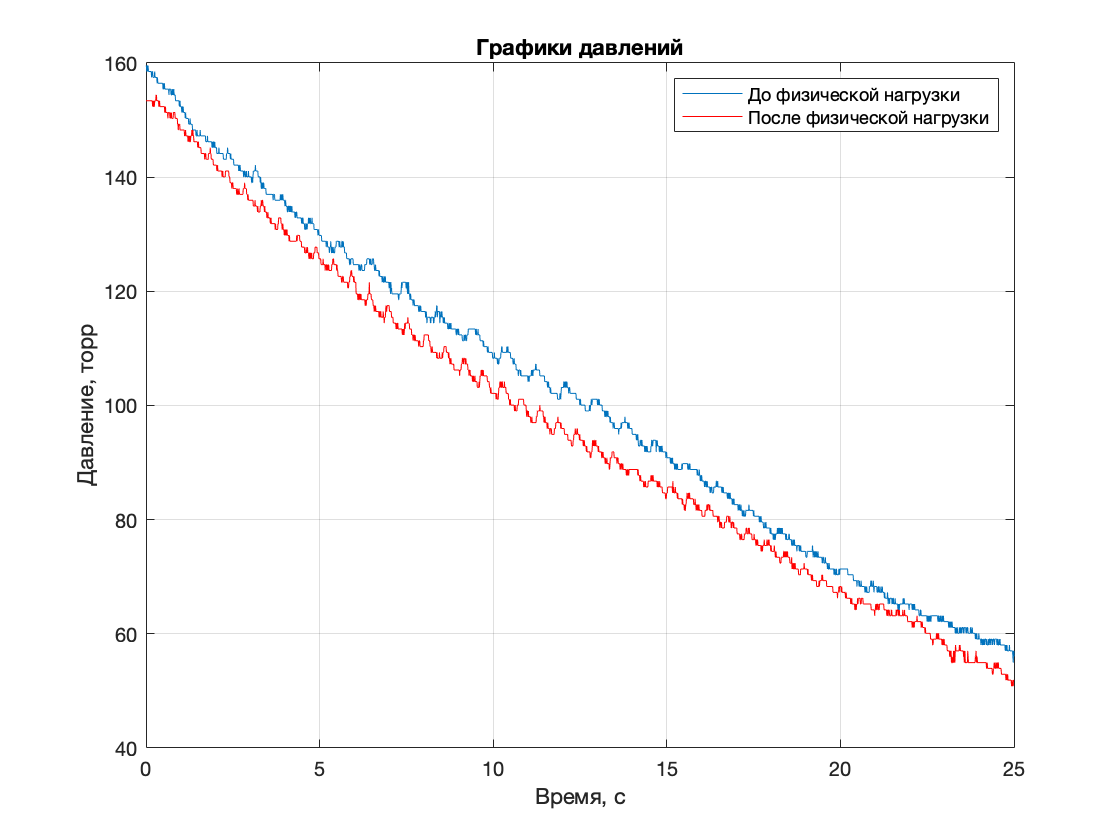

dt = 0.01;

x1 = load('/Users/karimvafin/Downloads/data/data_before.txt')';
x11 = polyval(k, x1);
y1 = linspace(0, length(x1)*dt, length(x1));

f = figure('Name','Давление');

figure(f);

plot(y1, x11);
xlim([0,25]);
hold on;

x2 = load('/Users/karimvafin/Downloads/data/data_after.txt')';
x22 = polyval(k, x2);
y2 = linspace(0, length(x2)*dt, length(x2));

plot(y2, x22, 'r');
xlim([0,25]);
grid on;
title('Графики давлений');
xlabel('Время, с');
ylabel('Давление, торр');
legend('До физической нагрузки','После физической нагрузки');

saveas(f,'Давление.png');

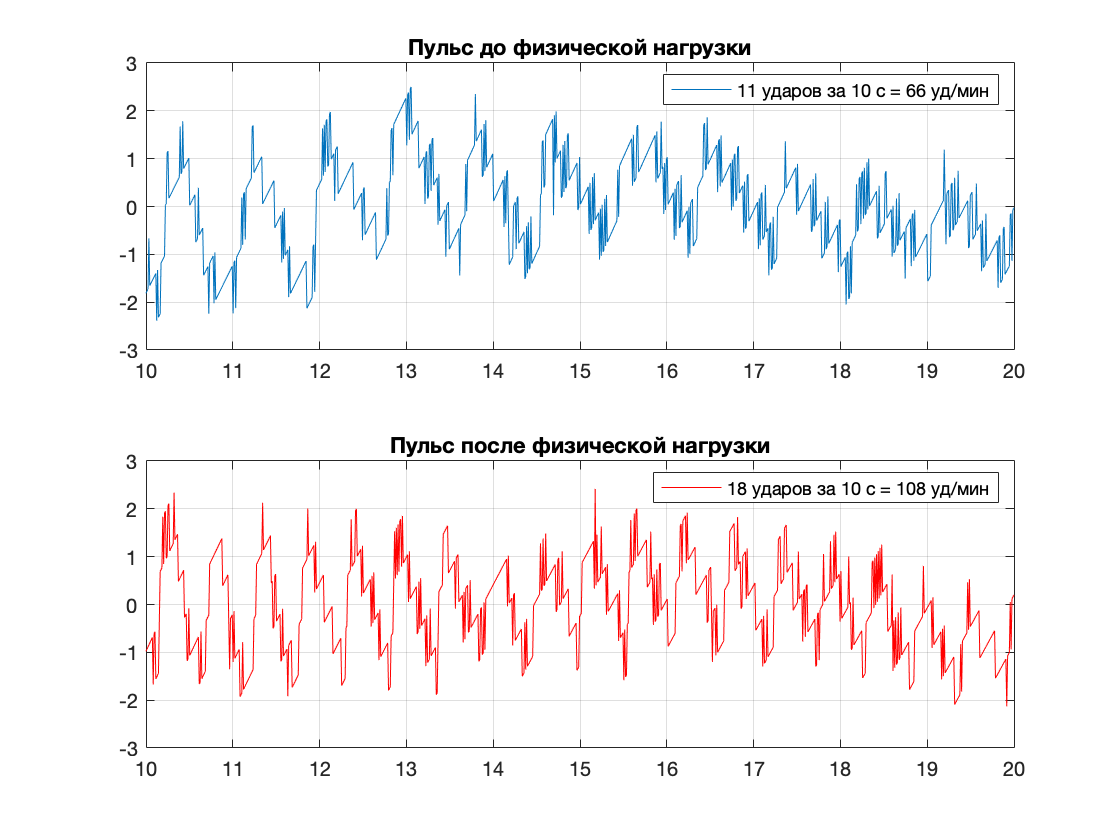

k1 = polyfit(y1, x11, 7);
k2 = polyfit(y2, x22, 5);

pulse1 = x11 - polyval(k1, y1);
pulse2 = x22 - polyval(k2, y2);

f2 = figure("Name", 'Графики пульса', 'NumberTitle',"off");

subplot(2, 1, 1);
plot(y1, pulse1);
grid on;
title('Пульс до физической нагрузки');
xlim([10,20]);
legend('11 ударов за 10 с = 66 уд/мин');

subplot(2, 1, 2);
plot(y2, pulse2, 'r');
grid on;
title('Пульс после физической нагрузки');
xlim([10,20]);
legend('18 ударов за 10 с = 108 уд/мин');

saveas(f2, 'pulse.png');